# **Lineær Regresjon**

clear
clf

X = [22.3 21.4 21.8 22.3 22.3 22.6 22.7 22.7 23.0 23.0 23.3 23.5 23.6 23.6 24.1 24.1 24.1 24.8 25.1 25.5];
Y = [36.8 39.9 43.0 42.2 44.1 47.0 44.0 42.0 43.5 47.9 41.0 44.3 42.2 46.5 43.7 42.8 44.5 42.3 46.0 42.0];
disp("x")

x


disp(X);

  Columns 1 through 6
                      22.3                      21.4                      21.8                      22.3                      22.3                      22.6
  Columns 7 through 12
                      22.7                      22.7                        23                        23                      23.3                      23.5
  Columns 13 through 18
                      23.6                      23.6                      24.1                      24.1                      24.1                      24.8
  Columns 19 through 20
                      25.1                      25.5


disp("y")

y


disp(Y);

  Columns 1 through 6
                      36.8                      39.9                        43                      42.2                      44.1                        47
  Columns 7 through 12
                        44                        42                      43.5                      47.9                        41                      44.3
  Columns 13 through 18
                      42.2                      46.5                      43.7                      42.8                      44.5                      42.3
  Columns 19 through 20
                        46                        42




if length(X) ~= length(Y)
    disp("ERROR: CHECK ARRAY LENGTH")
end

**Basic info**

xMean = mean(X);
yMean = mean(Y);
n = length(X);
fprintf("x mean: %.3f\ny mean: %.3f\nn: %d", xMean, yMean, n)

x mean: 23.290
y mean: 43.285
n: 20

**Regresjonslinje**

Sxx = 0;
for i = 1 : length(X)
Sxx = Sxx + X(i)^2;
end
Sxx = Sxx - n * xMean^2;
Sxx_double = double(Sxx);

Sxy = 0;
for i = 1 : length(X)
Sxy = Sxy + X(i)*Y(i);
end
Sxy = Sxy - n * xMean * yMean;

Syy = 0;
for i = 1 : length(X)
Syy = Syy + ( Y(i)-yMean)^2;
end

beta = Sxy/Sxx;
alfa = yMean - beta * xMean;

syms x
y_hat(x) = alfa + beta * x;

r = Sxy / ( sqrt(Sxx) * sqrt(Syy) );
forklaringsgrad = r^2;

fprintf("Sxx = %s = %.3f", Sxx, double(Sxx));

Sxx = 2.271800e+01 = 22.718

fprintf("Sxy = %s = %.3f", Sxy, double(Sxy));

Sxy = 1.224700e+01 = 12.247

fprintf("Syy = %s = %.3f", Syy, double(Syy));

Syy = 1.223855e+02 = 122.386

fprintf("Alfa =  %.3f",alfa)

Alfa =  30.730

fprintf("Beta =  %.3f",beta)

Beta =  0.539

**Forklaringsgrad**

fprintf("r = %.3f", r);

r = 0.232

fprintf("Forklaringsgrad = %.4f", forklaringsgrad);

Forklaringsgrad = 0.0539

fprintf("%.2f %% av variasjonen i observasjonene Y kan forklares med den lineære modellen", forklaringsgrad*100)

5.39 % av variasjonen i observasjonene Y kan forklares med den lineære modellen

**Finn estimert verdi for Y(x)**

xInput = 15;
est = double(y_hat(xInput));
fprintf("Estimert verdi: %.2f", double(est))

Estimert verdi: 38.82

# **Konfidensintervall for lineær regresjon**

fprintf("Frihetsgrader n-2 = %d", n-2);

Frihetsgrader n-2 = 18

**Om utfylling av kji 1 og kji 2**

Se i tabell over kvantiler i chi-fordelingen.

Bruk oppgitte frihetsgrader og finn

kji 1 = verdi i tabellen for (alfa / 2)

kji 2 = verdi i tabellen for (1-alfa /2)

Eksempel: 95% konfidensintervall, 18 frihetsgrader

             -> kji 1: verdi (0.5 / 2 = 0.25) med v = 18 frihetsgrader i tabellen => 31.53

             -> kji 2: verdi(1-0.05/2 ) = 0.975) med v = 18 frihetsgrader i tabellen => 8.23


chiSquaredVal1 = 31.53;
chiSquaredVal2 = 8.23; 

**Om utfylling av t_a / 2**

Se i tabell over kvantiler i student T fordelingen. Bruk frihetsgrader oppgitt ovenfor.

Eksempel: 95% konfidensintervall, 18 frihetsgrader.

            -> t_a / 2: verdo(0.5 / 2) med v = 18 frihetsgrader i tabellen => 2.101

t_a_Div2 = 2.101;

**Om utfylling av x**

x verdien brukes ved utregning av E(Y).

Det er altså et konfidensintervall for et spesifikt tilfelle av x.

x blir gjerne oppgitt i spørsmål.

x = 15;
See = Syy - beta^2*Sxx;
s_squared = See / (n - 2);
s = sqrt(s_squared);

konfidens_b = [beta - (t_a_Div2) * (s / Sxx), beta + (t_a_Div2) * (s / Sxx)];
konfidens_a = [alfa - (t_a_Div2) * s * sqrt((1 / n) + (xMean^2 / Sxx)), alfa + (t_a_Div2) * s * sqrt((1 / n) + (xMean^2 / Sxx))];
konfidens_varians = [( (n - 2) * s^2 ) / (chiSquaredVal1), ( (n - 2) * s^2 / chiSquaredVal2)];
konfidens_E_Y = [alfa + beta * x - t_a_Div2 * s * sqrt((1/n)+ ((x - ( xMean)^2 / Sxx ))),
    alfa + beta * x + t_a_Div2 * s * sqrt((1/n)+ ((x - ( xMean)^2 / Sxx )))] ;

fprintf("S_EE = %.3f", See);

S_EE = 115.783

fprintf("s = %.3f", s);

s = 2.536

fprintf("s^2 = %.3f", s_squared);

s^2 = 6.432

fprintf("Konfidensintervall for alfa: [%.3f, %3.f]",konfidens_a(1), konfidens_a(2));

Konfidensintervall for alfa: [4.665,  57]

fprintf("Konfidensintervall for beta: [%.3f, %3.f]",konfidens_b(1), konfidens_b(2));

Konfidensintervall for beta: [0.305,   1]


fprintf("Konfidensintervall for variansen: [%.3f, %3.f]",konfidens_varians(1), konfidens_varians(2));

Konfidensintervall for variansen: [3.672,  14]

fprintf("Konfidensintervall for E(Y): [%.3f, %3.f]",konfidens_E_Y(1), konfidens_E_Y(2));

Konfidensintervall for E(Y): [38.816,  39]

# **Plot**

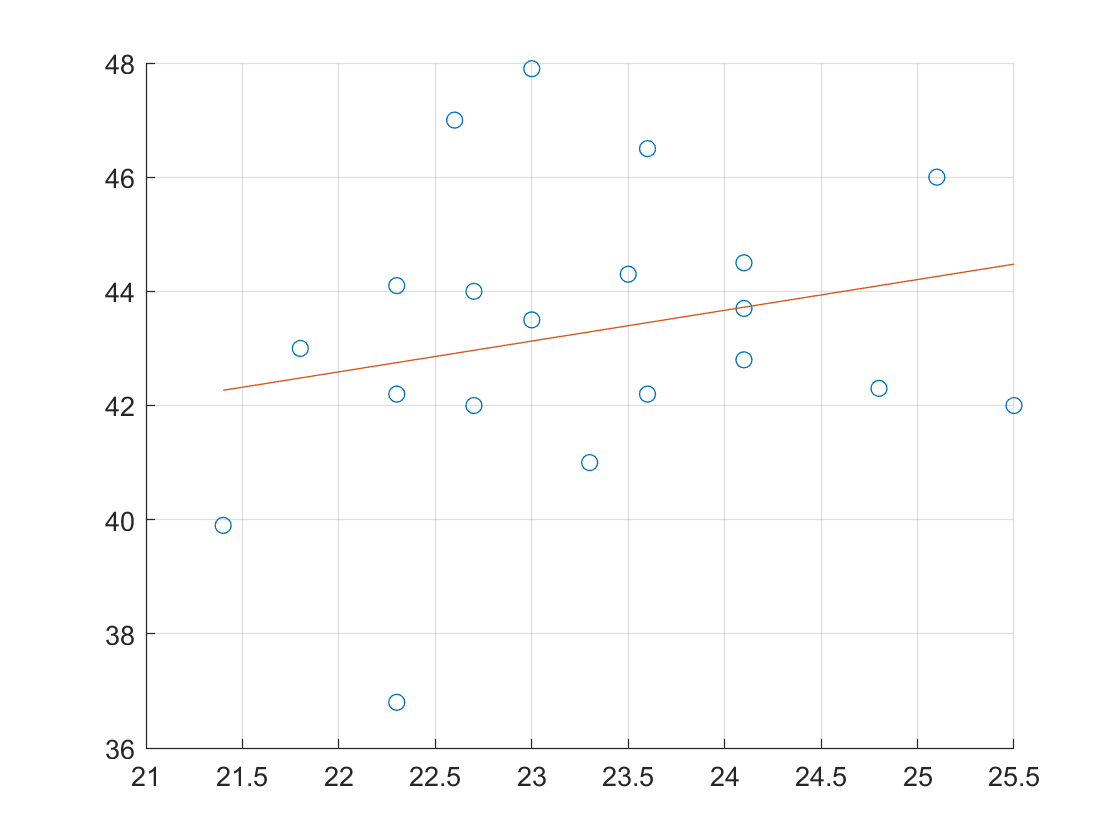

%Plot
scatter(X,Y)
grid
hold on
fplot(y_hat,[min(X) max(X)])